# AutoDRIVE Ecosystem | Nigel - Center of Mass Identification

## Clear the workspace

close all;
clear;
clc;

## Measurements

L = 0.14155; % Wheelbase (m)
Tf = 0.14724; % Front trackwidth (m)
Tr = 0.14724; % Rear trackwidth (m)
T = (Tf+Tr)/2; % Average trackwidth (m)
H = 0.25680; % Height (m)

x_int = 0.0071; % XY-plane intersection point from geometrical center (x-coordinate) of chassis (m)
y_int = 0.0000; % XY-plane intersection point from geometrical center (y-coordinate) of chassis (m)
z_int = 0.0923+0.007; % XZ/YZ-plane intersection point from geometrical center (z-coordinate) of chassis (m)

## CG position measurements

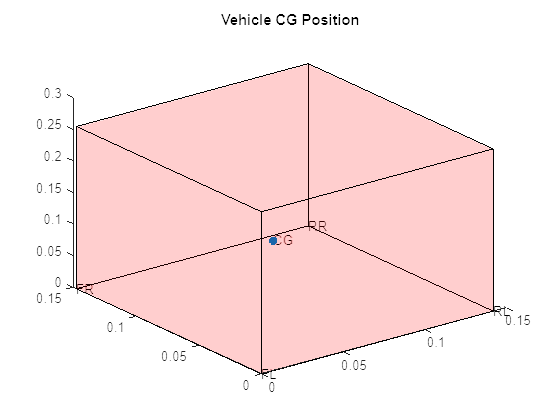

% Coordiantes of box based on wheelbase, trackwidth and height of the
% vehicle
coord = [...
    0 0 0;
    L 0 0;
    L Tr 0;
    0 Tf 0;
    0 0 H;
    L 0 H;
    L Tr H;
    0 Tf H];

% Connectivity matrix to specify how each point needs to be connected
% (each column specifies how polygon needs to be connected)
idx = [4 8 5 1 4; 1 5 6 2 1; 2 6 7 3 2; 3 7 8 4 3; 5 8 7 6 5; 1 4 3 2 1]';

xc = coord(:,1);
yc = coord(:,2);
zc = coord(:,3);

x_cg = L/2 - x_int;
y_cg = T/2 - y_int;
z_cg = z_int;

figure(1)
title('Vehicle CG Position')
patch(xc(idx), yc(idx), zc(idx), 'r', 'facealpha', 0.1);
hold on
plot3(x_cg,y_cg,z_cg, '*','LineWidth',3)
text(0,0,0,'FL')
text(L,0,0,'RL')
text(L,Tr,0,'RR')
text(0,Tf,0,'FR')
text(x_cg,y_cg,z_cg,'CG')
hold off
view(3);

result = sprintf('Vehicle CG Position:\nx: %.4f y: %.4f z: %.4f', x_cg, y_cg, z_cg);
disp(result);

Vehicle CG Position:
x: 0.0637 y: 0.0736 z: 0.0993
